# Performance Analysis

*Functions*

clear; clc;

function [rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points)
    G = @(z) (1/pi) * exp(-abs(z).^2);
    
    % Create complex quadrature nodes matrix
    N = length(nodes);
    z_matrix = createComplexNodesMatrix(nodes);
    disp('Z MATRIX')
    disp(z_matrix)
    
    % Create Pi matrix
    M = length(X);
    pi_matrix = createPiMatrix(M, N, weights);
    disp('PI MATRIX')
    disp(pi_matrix)
    
    % Create G matrix
    g1_matrix = createGMatrix(X, z_matrix, SNR, G);
    disp('G MATRIX')
    disp(g1_matrix)
    
    % Compute rho values (always between 0 and 1)
    rho_values = linspace(0, 1, num_points);
    
    % Preallocate Eo_rho
    Eo_rho = zeros(size(rho_values));
    
    % Compute E0(rho) for different rho values
    for idx = 1:length(rho_values)
        rho = rho_values(idx);
        
        % Compute intermediate terms
        g_powered = g1_matrix.^(1 / (1 + rho));
        qg_rho = Q * g_powered;
        qg_rho_t = qg_rho.^rho;
        pi_g_rho = pi_matrix .* (g1_matrix.^(-rho / (1 + rho)));
        
        % Combine results
        component_second = Q * (pi_g_rho * qg_rho_t');
        
        % Final calculation for E_0(rho)
        Eo_rho(idx) = -log2((1 / pi) * component_second);
    end
end

function z_matrix = createComplexNodesMatrix(nodes)
    N = length(nodes);
    z_matrix = zeros(N, N);
    for i = 1:N
        for j = 1:N
            z_matrix(i,j) = nodes(i) + 1i*nodes(j);
        end
    end
end

function pi_matrix = createPiMatrix(M, N, weights)
    pi_matrix = zeros(M, N^2*M);
    pi_block = weights(1)*weights(2);
    for i = 1:M
        start_col = (i-1)*N^2 + 1;
        end_col = i*N^2;
        pi_matrix(i, start_col:end_col) = pi_block;
    end
end

function g1_matrix = createGMatrix(X, z_matrix, SNR, G)
    M = length(X);
    N = size(z_matrix, 1);
    g1_matrix = zeros(M, N^2*M);
    
    for i = 1:M % Source symbols
        for j = 1:M % Received symbols
            for k = 1:N % First quadrature nodes
                for l = 1:N % Second quadrature nodes
                    % Compute column index
                    col_idx = (j-1)*N^2 + (k-1)*N + l;
                    
                    % Compute G values
                    g1_matrix(i, col_idx) = G(z_matrix(k,l) + (sqrt(SNR)*X(i)) - (sqrt(SNR)*X(j)));
                end
            end
        end
    end
end

# Using different constellation sizes

*Investigar els temps d'execució en funció del tamany de la constel·lació*

Z MATRIX
 -0.707106781186547 - 0.707106781186547i -0.707106781186547 + 0.707106781186547i
  0.707106781186547 - 0.707106781186547i  0.707106781186547 + 0.707106781186547i

PI MATRIX
   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448

G MATRIX
   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638   0.000126767353884   0.000126767353884   0.036286744811575   0.036286744811575
   0.036286744811575   0.036286744811575   0.000126767353884   0.000126767353884   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638

Z MATRIX
 -0.707106781186547 - 0.707106781186547i -0.707106781186547 + 0.707106781186547i
  0.707106781186547 - 0.707106781186547i  0.707106781186547 + 0.707106781

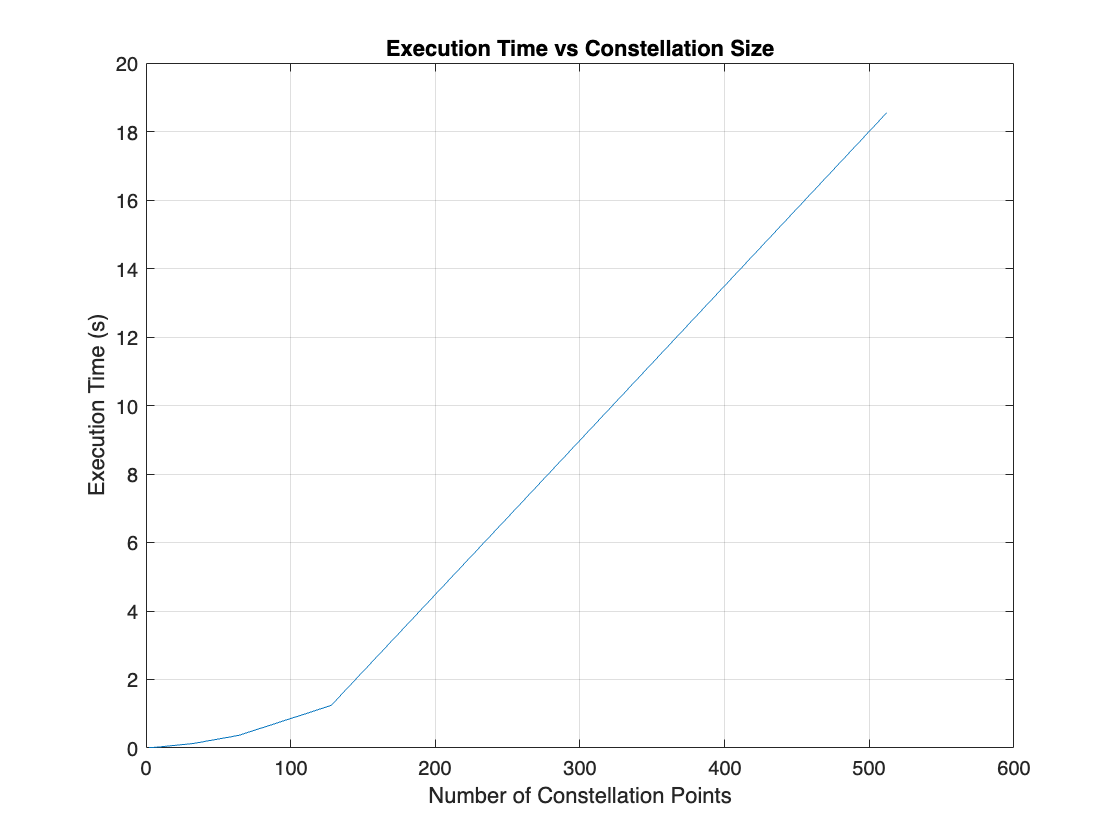

Size	Time
2 -> 0.015127 s
4 -> 0.009995 s
8 -> 0.026750 s
16 -> 0.066578 s
32 -> 0.163069 s
64 -> 0.421541 s
128 -> 1.273352 s
256 -> 6.699174 s
512 -> 20.979020 s


function runConstellationPerformance()    
    constellation_sizes = [2, 4, 8, 16, 32, 64, 128, 256, 512, 1028];
    
    execution_times = zeros(size(constellation_sizes));
    constellation_points = cell(size(constellation_sizes));
    
    SNR = 1;
    num_points = 1000;
    nodes = [-1/sqrt(2), 1/sqrt(2)];
    weights = [sqrt(pi)/2, sqrt(pi)/2];
    
    for idx = 1:length(constellation_sizes)
        % Current constellation size
        M = constellation_sizes(idx);
        
        % Generate and normalize constellation
        amplitude = 3;
        X = linspace(-amplitude, amplitude, M);
        avg_energy = mean(X.^2);
        X = X / sqrt(avg_energy);
        
        % Store constellation points
        constellation_points{idx} = X;
        
        % Equal probabilities
        Q = ones(1, M) / M;
        
        % Measure execution time
        tic;
        [~, ~] = computeEO(X, Q, nodes, weights, SNR, num_points);
        execution_times(idx) = toc;
    end
    
    figure;
    plot(constellation_sizes, execution_times);
    title('Execution Time vs Constellation Size');
    xlabel('Number of Constellation Points');
    ylabel('Execution Time (s)');
    grid on;
    
    fprintf('Size\tTime\n');
    for idx = 1:length(constellation_sizes)
        fprintf('%d -> %.6f s\n', constellation_sizes(idx), execution_times(idx));
    end
end

runConstellationPerformance();

# Using different quadrature nodes and weights

*Implementar més nodes de la *[*quadratura*](https://www.google.com/url?q=https://mathworld.wolfram.com/Hermite-GaussQuadrature.html&source=gmail-imap&ust=1733482875000000&usg=AOvVaw1pdL2XpO_rGb9eT_Cz1OGY)

M = 2;  % Constellation size
amplitude = 3;
X = linspace(-amplitude, amplitude, M);
avg_energy = mean(X.^2);
X = X / sqrt(avg_energy);
Q = ones(1, M) / M;
disp(X)

    -1     1



% Fixed parameters
SNR = 1;
num_points = 1000;

N = 2;  % Number of points
[nodes, weights] = GaussHermite_Locations_Weights(N);
disp(nodes)

  -0.707106781186548
   0.707106781186547



disp(weights)

   0.886226925452758
   0.886226925452758



% Compute E0(rho)
tic;
[rho_values, Eo_rho] = computeEO(X, Q, nodes, weights, SNR, num_points);

Z MATRIX
 -0.707106781186548 - 0.707106781186548i -0.707106781186548 + 0.707106781186547i
  0.707106781186547 - 0.707106781186548i  0.707106781186547 + 0.707106781186547i

PI MATRIX
   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448                   0                   0                   0                   0
                   0                   0                   0                   0   0.785398163397448   0.785398163397448   0.785398163397448   0.785398163397448

G MATRIX
   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638   0.000126767353884   0.000126767353884   0.036286744811575   0.036286744811575
   0.036286744811575   0.036286744811575   0.000126767353884   0.000126767353884   0.117099663048638   0.117099663048638   0.117099663048638   0.117099663048638



execution_time = toc;

fprintf('Execution time: %.6fs\n', execution_time);

Execution time: 0.003701s


figure;
plot(rho_values, Eo_rho);
title(['E_0(ρ) with N = ', num2str(length(nodes))]);
xlabel('ρ');
ylabel('E_0(ρ)');
grid on;

# Optimization

Implementar l'optimizació de la ρ trobant el màxim de E0(ρ) – ρ·R per ρ entre 0 i 1, per exemple per SNR = 1 i R = 0.5

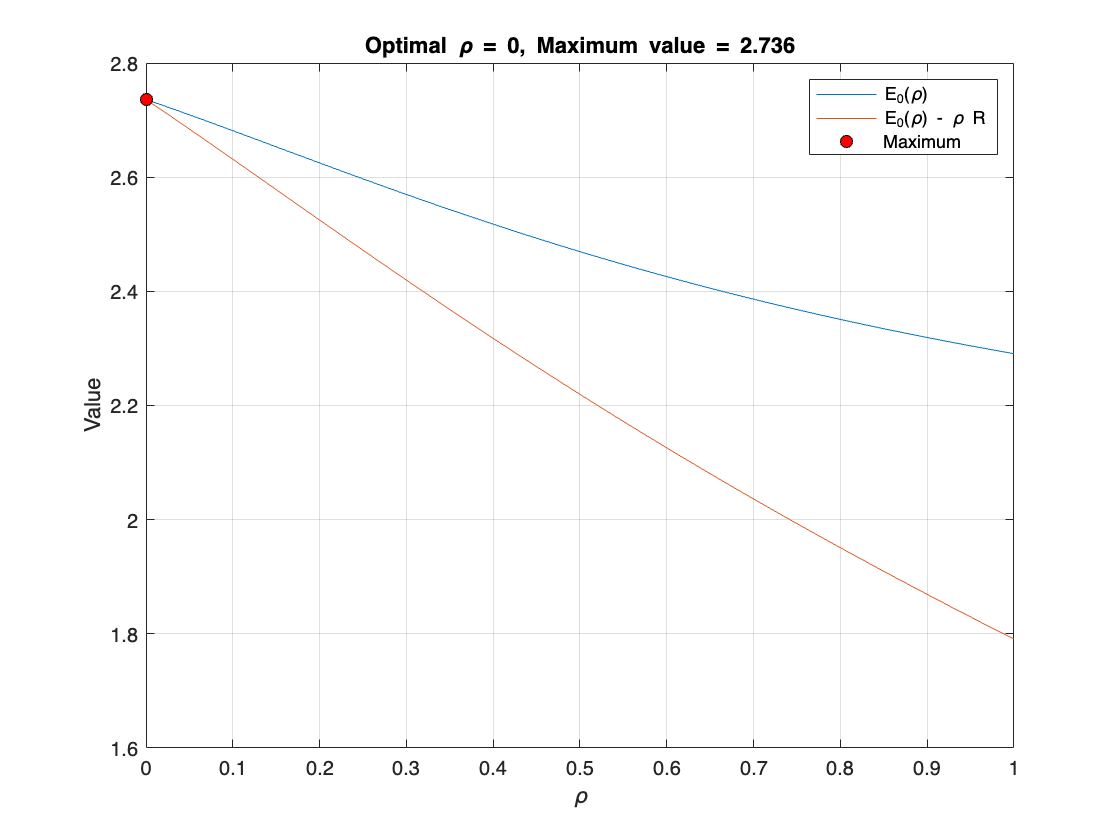

% Define R
R = 0.5;

% Calculate E0(ρ) - ρ·R
toOptimize = Eo_rho - R*rho_values;

% Find maximum and its index
[max_value, max_idx] = max(toOptimize);
optimal_rho = rho_values(max_idx);

% Plot
figure;
plot(rho_values, Eo_rho);
hold on;
plot(rho_values, toOptimize);
plot(optimal_rho, max_value, 'ko', 'MarkerFaceColor', 'r');
xlabel('\rho');
ylabel('Value');
legend('E_0(\rho)', 'E_0(\rho) - \rho R', 'Maximum');
title(['Optimal \rho = ', num2str(optimal_rho), ', Maximum value = ', num2str(max_value)]);
grid on;

% Define R
R = 0.5;

cvx_begin

    variable rho(1)
    expression 
    minimize(Eo_rho(rho) - rho*R)

Unable to use a value of type cvx as an index.

    subject to
        0 <= rho <= 1
cvx_end

figure;
plot(rho_values, Eo_rho);
hold on;
plot(rho_values, toOptimize);
plot(optimal_rho, max_value, 'ko', 'MarkerFaceColor', 'r');
xlabel('\rho');
ylabel('Value');
legend('E_0(\rho)', 'E_0(\rho) - \rho R', 'Maximum');
title(['Optimal \rho = ', num2str(optimal_rho), ', Maximum value = ', num2str(max_value)]);
grid on;